# 2.1. Матричные операции

**Лекция**

## Создание матриц

Матрицы можно создавать вручную. Порядок ручного ввода элементов таков:

A = [1 2 3; 4 5 6]

A =      1     2     3
     4     5     6


Все строки должны иметь одинаковое количество компонент: 

Если всё-таки требуется построить матрицу без компонент, то следует определить недостающие компоненты как `NaN`:

Матрица может быть получена конкатенацией других матриц и векторов. Главное условие - совместимость размерностей. 

Создание матрицы 3х3 из матрицы 2х3 и вектора-строки 1х3:

B = [7 8 9]

B =      7     8     9


C = [A;B]

C =      1     2     3
     4     5     6
     7     8     9


Пример несовпадения размерностей: 

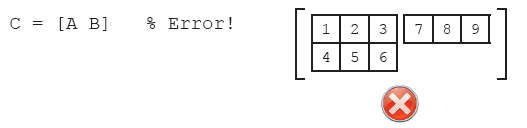

## Создание матриц с помощью функций

В MATLAB есть множество функций, в возможностях которых заложено создание матриц. Типичный синтаксис подобной функции выглядит так:

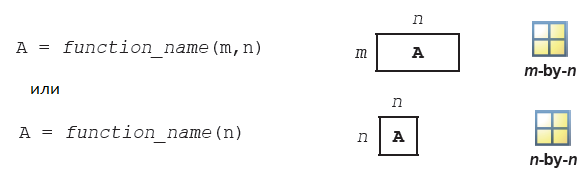

Такими функциями, например, являются функции создания нулевой матрицы (`zeros`) и матрицы, все компоненты которой - единицы (`ones`):

X = zeros(2,3)

X =      0     0     0
     0     0     0


Y = ones(2)

Y =      1     1
     1     1


Матрицы также можно создавать с помощью ранее описанных функций `rand`, `randi` и `randn`:

rand(2,4)

ans =     0.1259    0.0723    0.7483    0.7844
    0.9115    0.3755    0.6013    0.3302


randi([15,111],3,2)

ans =     94   107
    93    94
    65   100


randn(3)

ans =     0.7646    1.5166   -0.8733
   -0.1839   -1.3583   -0.5613
    0.9543   -0.3303   -1.1843


Единичная матрица создается с помощью функции `eye`, а диагональная матрица создается из вектора с помощью `diag`:

eye(4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


diag(B)

ans =      7     0     0
     0     8     0
     0     0     9


Список других функций, создающих матрицы, можно посмотреть, введя команду

## Доступ к данным матрицы

К любой компоненте матрицы можно обращаться по номеру строки и столбца. Её также можно изменять. Также, как и в случае с векторами можно использовать номер **end**:

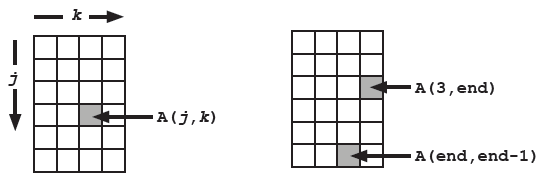

Из матрицы можно также выделить сразу набор данных способом, аналогичным используемому для векторов:

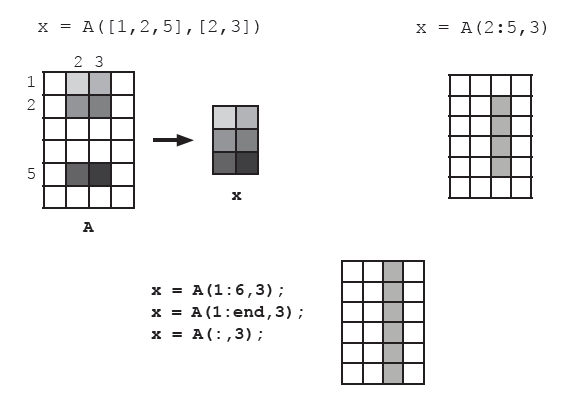

Пример:

D = [A,X;B,C(3,:)]

D =      1     2     3     0     0     0
     4     5     6     0     0     0
     7     8     9     7     8     9


D(2:3, 3:5)

ans =      6     0     0
     9     7     8


D([1,3], [4:end, 1])

ans =      0     0     0     1
     7     8     9     7


## Операции над матрицами

Арифметические операции над матрицами производятся аналогично векторам:

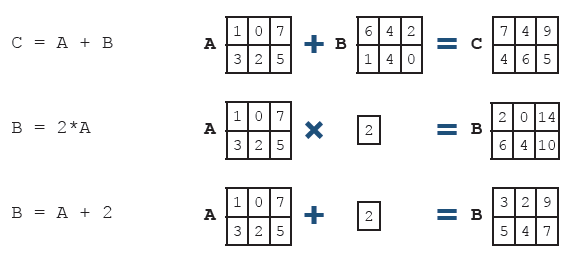

Для покомпонентного умножения матриц перед знаком умножения следует ставить точку (как для векторов):

К матрице можно также прибавлять вектор-строку, количество столбцов которой соответствует количеству столбцов матрицы. Аналогично можно прибавлять к матрице вектор-столбец, количество строк которого совпадает с количеством строк матрицы: 

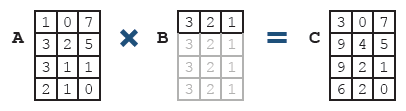

Пример:

2*ones(3) + [3; 2; 1] + [1, 2, 3]

ans =      6     7     8
     5     6     7
     4     5     6


Матричное перемножение по правилам линейной алгебры производится с помощью оператора умножения: 

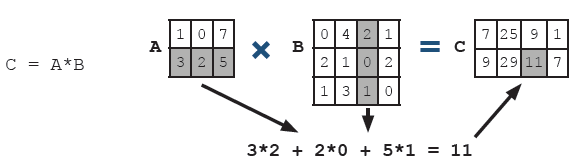

Операция перемножения двух матриц возможна, если количество столбцов первой матрицы равно количеству строк второй: 

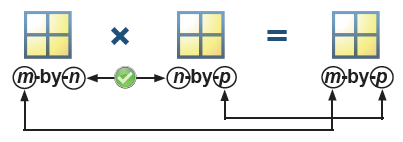

Операция матричного деления интерпретируется как решение матричного уравнения. Вследствие некоммутативности матричного произведения в MATLAB используются обе черты: прямая (/) и обратная (\) как решение следующих уравнений: 

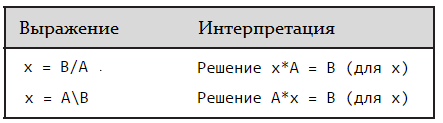

B

B =      7     8     9


A

A =      1     2     3
     4     5     6


x = B/A

x =    -1.0000    2.0000


Математические функции применимы к матрицам таким же образом, как и вектора - поэлементным преобразованием:

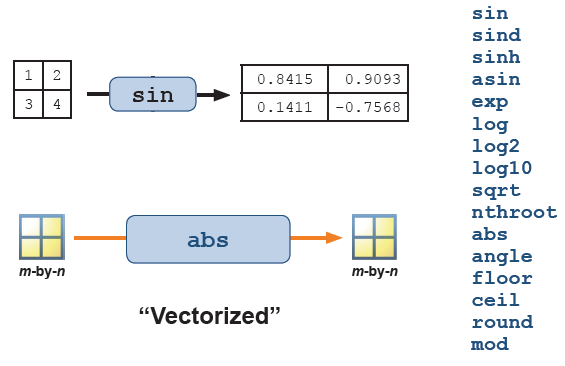

Статистические операции, применяемые к матрице, могут применяться как к строкам, так и к столбцам отдельно. За это отвечает параметр направления: "1" означает счет по столбцам, "2" означает счет по строкам:

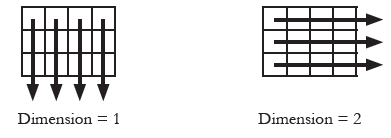

На примере функции `mean` это выглядит так:

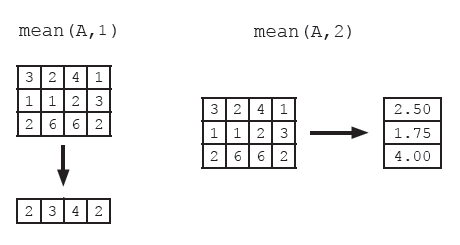

Функции, которые разделяют матрицу на векторы для своей работы представлены в таблице:

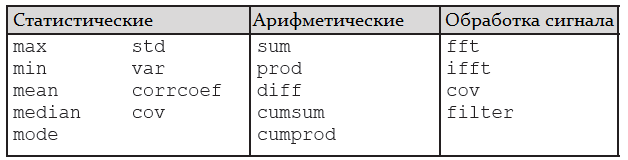

Из исходной матрицы с помощью команды `reshape` можно создать матрицу с теми же компонентами, что и исходная, но с измененной размерностью:

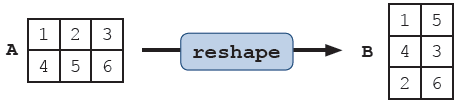

A = [1,2,3; 4,5,6]

A =      1     2     3
     4     5     6


B = reshape(A,3,2)

B =      1     5
     4     3
     2     6


C = reshape(A, [],1)

C =      1
     4
     2
     5
     3
     6


D = reshape(A, 1,[])

D =      1     4     2     5     3     6


К матрицам также применимы функции: взятие обратной матрицы (`inv`), нахождение определителя (`det`), нахождение следа (`trace`), нахождение собственных векторов/значений (`eig`), вычисление матричной экспоненты (`expm`), нахождение LUP-разложения (`lu`).

Рассмотрим их на примере матрицы:

M = 3*ones(3) - 2*diag([3 1 8])*[-1, 2, 3; 4, 5, 6; 9, 8, 7]

M =      9    -9   -15
    -5    -7    -9
  -141  -125  -109


inv(M)

ans =     0.0833   -0.2058    0.0055
   -0.1667    0.7127   -0.0359
    0.0833   -0.5511    0.0249


det(M)

ans = -4.3440e+03

trace(M)

ans = -107

[l,V] = eig(M)

l =     0.1088    0.6307    0.2311
    0.0746    0.1151   -0.7771
    0.9913   -0.7675    0.5854


V =  -133.8785         0         0
         0   25.6116         0
         0         0    1.2669


expm(M)

ans = 	1.0e+11 *

    1.1161    0.2268   -0.1395
    0.2037    0.0414   -0.0255
   -1.3582   -0.2760    0.1698


[L,U,P] = lu(M)

L =     1.0000         0         0
   -0.0638    1.0000         0
    0.0355    0.1512    1.0000


U =  -141.0000 -125.0000 -109.0000
         0  -16.9787  -21.9574
         0         0   -1.8145


P =      0     0     1
     1     0     0
     0     1     0


Ранг матрицы определяется с помощью команды `rank`:

R = [1,2,3; 4,5,6; 8,10,12]

R =      1     2     3
     4     5     6
     8    10    12


rank(R)

ans = 2